# 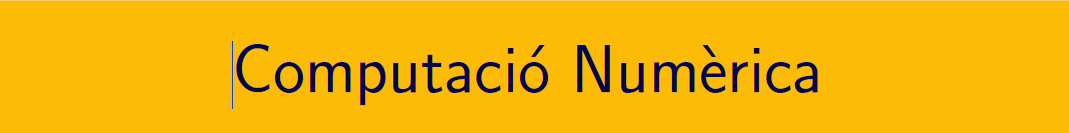

================================================================================

# Pràctica 10. Integració aproximada de funcions i dades.

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-Lab9.pdf i en el document CN_full6.pdf, els podeu trobar en el campus virtual. 

## 1 APRENEM .....

### 1.1 MATLAB® - Trapezis

Consulta la documentació i exemples de [trapz](https://es.mathworks.com/help/matlab/ref/trapz.html) i l'exemple de [integració de dades numèriques](https://es.mathworks.com/help/matlab/math/integration-of-numeric-data.html). Per al mètode de Simpson, podeu fer ús de l'expressió  $ S(f,h)=\displaystyle\frac{4}{3}T\left(f,\frac{h}{2}\right)-\frac{1}{3}T(f,h)$que relaciona la fórmula dels trapezis i la regla de Simpson. També podeu fer ús dels codis de [codis integració aproximada](http://www.math.mcgill.ca/gantumur/math578f09/?Matlab_files) (revisar el codi)

### 1.2 MATLAB® - Romberg

Podeu fer ús dels codis de Matlab File Exchange, [codis](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) 

### 1.3 MATLAB® - Integració adaptativa

La partició de l'interval d'integració es construiex de tal manera que  `abs(q - Q) <= max(AbsTol,RelTol*abs(q)), amb q el valor calculat i Q el valor exacte. Consulteu `[integral](https://www.mathworks.com/help/matlab/ref/integral.html) en la documentació de MATLAB®

Cleve Moler, entre els seus codis del llibre *Numerical computing with Matlab* ens ha preparat una explicació gràfica del procediment. 

%  quadgui(@(x)humps(x),0,1,1.0e-2)
integral(@(x)humps(x),0,1,'RelTol',1e-8,'AbsTol',1e-13)

### 1.4  MATLAB® - Monte Carlo Simulation

Una petita introducció dels mètodes en MATLAB® es pot consultar a l'enllaç següent: [https://es.mathworks.com/discovery/monte-carlo-simulation.html](https://es.mathworks.com/discovery/monte-carlo-simulation.html)

Integració aproximada pel mètode de Montecarlo:  una explicació en el video del professor Craig McNeile a youtube [https://www.youtube.com/watch?v=AaCeUpSFHAk](https://www.youtube.com/watch?v=AaCeUpSFHAk) 

Que s'enten per Monte Carlo Simulation? Una classe del professor John Guttag en el Mit Course: [Introduction to Computational Thinking and Data Science](https://ocw.mit.edu/courses/electrical-engineering-and-computer-science/6-0002-introduction-to-computational-thinking-and-data-science-fall-2016/). Disponible a l'enllaç [https://www.youtube.com/watch?v=OgO1gpXSUzU](https://www.youtube.com/watch?v=OgO1gpXSUzU)

## 2 PRACTIQUEM ....

### Exercici 1. Aplicació dades discretes

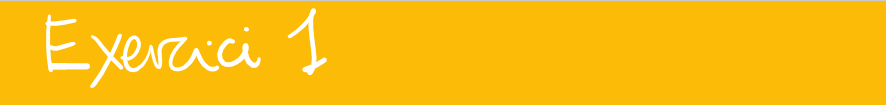

Trobeu la distància que ha recorregut un mòvil a partit de les dades de la següent taula

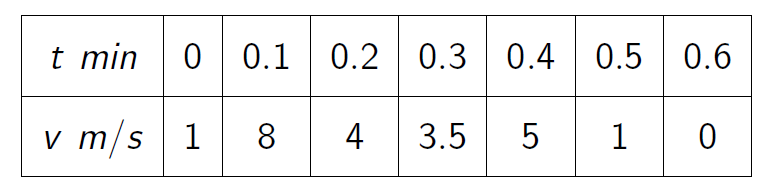

time = linspace(0,0.6,7);
vel = [1 8 4 3.5 5 1 0];

- Representa gràficament les dades de la taula

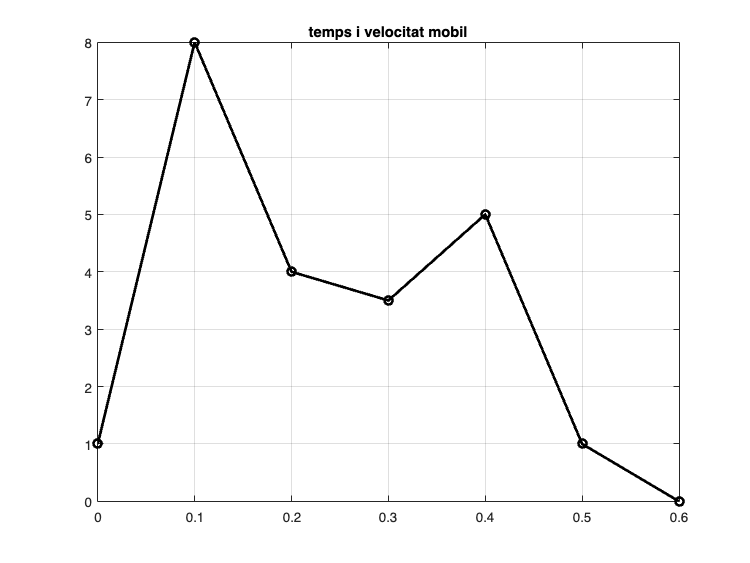

plot(time,vel,'-ko', 'LineWidth',2), title('temps i velocitat mobil'),grid

- Explica l'estratègia i dona el resultat pel mètode del punt mig

h = 0.2*60

h =     12

w = [0 1 0 1 0 1 0] %perquè seria 0 1 0 1 0 1 0 i només compten els punts del mig perquè es un rectangle

w =      0     1     0     1     0     1     0


i_r = h*sum(w.*vel) % metres, me'n sembla que posa 12 perquè es la mida de la base del recangle

i_r =    150

- Explica l'estratègia i dona el resultat pel mètode dels trapezis

t = time*60;
dist_T = trapz(t,vel)   % metres

dist_T =           132

w = [1 2 2 2 2 2 1]

w =      1     2     2     2     2     2     1


h = diff(time*60)

h =             6            6            6            6            6            6


i_t =h(1)/2*w*vel'

i_t =           132

- Explica l'estratègia i dona el resultat pel mètode de Simpson

w = [1 4 2 4 2 4 1]

w =      1     4     2     4     2     4     1


h = diff(time*60)

h =             6            6            6            6            6            6


i_t =h(1)/3*w*vel'

i_t =           138

%h = 0.1*60;
%I_s = h/3*sum(w.*vel)

### Exercici 2. Aplicació per funcions - Fórmules simples

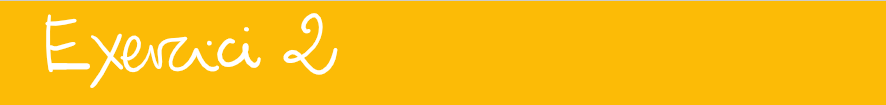

                         
$$\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,=\frac{\pi}{2}$$


vc = pi/2

vc =        1.5708

f = @(x)2./(1+x.^2);

- Calculeu, fent ús de la regla del punt mig el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (simple)

a = 0; b =1;
h = b-a; 
iR = h*f((a+b)/2)

iR =           1.6

dc = abs(iR-vc)

dc =      0.029204


I_pm = h*f((a+b)/2)

I_pm =           1.6

dc = abs(vc-I_pm)

dc =      0.029204

I_pm = midp(f,0,1,1)

I_pm =           1.6

- Calculeu, fent ús de la fórmula del trapezi el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$(simple)

a = 0; b =1;
h = b-a; 
iT = h/2*(f(a)+f(b))

iT =           1.5

dc = abs(iT-vc)

dc =      0.070796


I_t = h*(f(a)+f(b))/2

I_t =           1.5

dc = abs(vc-I_t)

dc =      0.070796

I_t = trap(f,0,1,1)

I_t =           1.5

x = [0,1]; 
y = f(x);
I_t = trapz(x,y)

I_t =           1.5

- Calculeu, fent ús de la regla Simpson el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (simple)

a = 0; b =1;
h = (b-a)/2; 
iS = h/3*(f(a)+4*f((a+b)/2)+f(b))

iS =        1.5667

dc = abs(iS-vc)

dc =     0.0041297


%a = 0; b = 1; h = (b-a)/2;
I_t = h*(f(a)+4*f((a+b)/2)+f(b))/3

I_t =        1.5667

dc = abs(vc-I_t)

dc =     0.0041297

I_s = simp(f,0,1,1)

I_s =        1.5667

### Exercici 3. Aplicació per funcions - Fórmules compostes

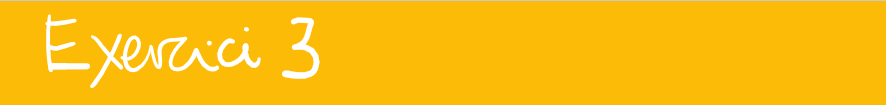

Podeu fer ús dels codis de [codis integració aproximada](http://www.math.mcgill.ca/gantumur/math578f09/?Matlab_files)

                         
$$\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,=\frac{\pi}{2}$$


clearvars;
f = @(x)2./(1+x.^2)
a = 0; b = 1;
vc = pi/2

- Calculeu, fent ús de la regla del punt mig el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (4 subintervals)

n = 4;
ir = midp(f,a,b,n)
dcR = abs(ir-pi/2)

% 0-*-1/4-*-1/2-*-3/4-*-1
a = 0; b = 1; n = 4;
h = (b-a)/n;
x = a+h/2:h:b;
I_pm = sum(f(x))*h
dc   = abs(vc-I_pm)
I_pm = midp(f,0,1,4)

- Calculeu, fent ús de la fórmula del trapezi el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (4 subintervals)

n = 4;
it = trap(f,a,b,n)
dcT = abs(it-pi/2)

a = 0; b = 1;
n = 4;
h = (b-a)/n;
x = a:h:b;
y = f(x);
I_t = trapz(x,y)
dc = abs(vc-I_t)
I_t = trap(f,0,1,4)

- Calculeu, fent ús de la regla Simpson el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (2 subintervals)

n = 2;
is = simp(f,a,b,n)
dcS = abs(is-pi/2)

% 0-1/2-1
a = 0; b = 1;
n = 2;
h = (b-a)/(2*n);
x = a:h:b;
y = f(x);
w = [1 4 2 4 1];
I_s = sum(w.*y)*h/3, dc = abs(vc-I_s)
I_s = simp(f,0,1,2)
dc = abs([I_pm,I_t,I_s]-vc) % error

### Exercici 4. Funcions amb singularitats

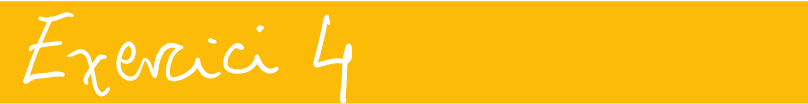

Calculeu $\displaystyle \int_0^{1} \frac{\sin t}{t}\,dt  \approx 0.946083070367 \pm 0.5e\!-\!12$

- Valor correcte

vc = 0.946083070367

vc =       0.94608

f = @(t)sin(t)./t;

- Regla del punt mig composta. Quants subintervals cal pendre?

a = 0; b = 1; 
f = @(x)sin(x)./x;
n = 10^6

n =      1000000

ir = midp(f,a,b,n)

ir =       0.94608

dcR = abs(ir-vc)

dcR =    1.2856e-13


% funció oberta
I_pm = midp(f,0,1,100)

I_pm =       0.94608

dc = abs(I_pm - vc)

dc =    1.2549e-06

- Regla dels trapezis composta. Quants subintervals cal pendre?

a = 0; b = 1; 
% f = @(x)sin(x)./x;
n = 200

n =    200

it = simp(@myF,a,b,n)

it =       0.94608

dcT = abs(it-vc)

dcT =    2.2216e-13


% funció tancada (problema t = 0)
I_t = trap(f,0,1,10)

I_t =    NaN

% 2 solució
I_t = trap(@myF,0,1,10)

I_t =       0.94583

% Quants subintervals?
% ((b-a)^3/24)*h^2*f''()
% |(1/24*n^2)*f''(x)| < 0.5e-12         PD: caldria fer una funció que donat 0.5e-12 retorni el nombre de subintervals
dc = abs(I_t - vc)

dc =      0.000251

### Exercici 5. Mètode de Romberg

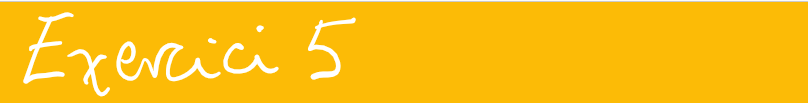

Calculeu mitjançant romberg$\displaystyle \int_0^{0.8} \frac{\sin t}{t}\,dt  \approx 0.772095 \pm 0.5e\!-\!6$

Apliqueu la taula d'extrapolació de romberg (podeu fer ús de [romberg.m](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) o un altre, verifiqueu el  vostre codi amb la taula següent)

format longG
a = 0; b = 0.8; n = 4;
IRom = romberg(@myF, a , b, 4 )

IRom =          0.758678045449761                         0                         0                         0
         0.768757365033531         0.772117138228121                         0                         0
         0.771262171110172         0.772097106469052         0.772095771018448                         0
         0.771887443653348         0.772095867834406         0.772095785258763           0.7720957854848


it = simp(@myF,a,b,4)

it =          0.772095867834406


format longG
vc = integral(@(x)myF(x),0,0.8,'RelTol',1e-8,'AbsTol',0.5e-16);

r = romberg(@myF,0,0.8,4)

r =          0.758678045449761                         0                         0                         0
         0.768757365033531         0.772117138228121                         0                         0
         0.771262171110172         0.772097106469052         0.772095771018448                         0
         0.771887443653348         0.772095867834406         0.772095785258763           0.7720957854848


abs(round(r - tril(vc*ones(size(r))),3,'significant'))

ans =                     0.0134                         0                         0                         0
                   0.00334                  2.14e-05                         0                         0
                  0.000834                  1.32e-06                  1.45e-08                         0
                  0.000208                  8.24e-08                  2.23e-10                   2.8e-12


Resposta 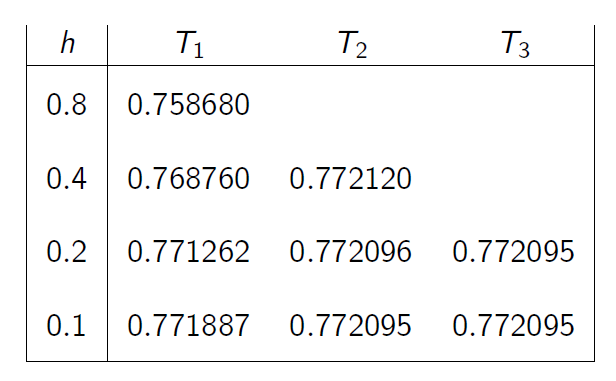

### Exercici 6. Mètode de Montecarlo

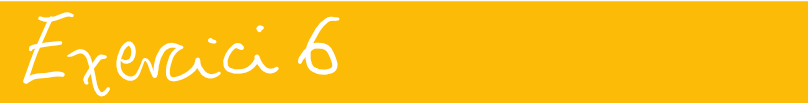

Calculeu els  valors  de    $\displaystyle\int_0^1 x dx = 1/2\,, \quad
\displaystyle\int_0^1 x^2 dx = 1/3\,, \quad
\displaystyle\int_0^4 x dx = 8\,, \quad
\displaystyle\int_{-1}^1 x dx = 1\,.

$

- Tipus I (valor esperat)

g = @(x)x 

g = function_handle with value:
    @(x)x

M = 10^6; %100000000
a = 0; b = 4;
x = a+ (b-a)*rand(M,1);
IM = (b-a)/M*sum(g(x))

IM =           8.00717968194744

ordre = 1/sqrt(M)   

ordre =                      0.001

dc = abs(IM-8)

dc =        0.00717968194744323



format shortG
g = @(x)x;
m = 1000000;
a = 0; b = 1;
x = a+(b-a)*rand(m,1);
y = g(x);
I_m = (b-a)/m*sum(y)

I_m = 0.4998

dc = abs(I_m - 1/2), ordre = 1/sqrt(m)

dc = 2.1009e-04

ordre = 1.0000e-03

- Tipus II (hit or miss)

M = 10^6

M = 1000000

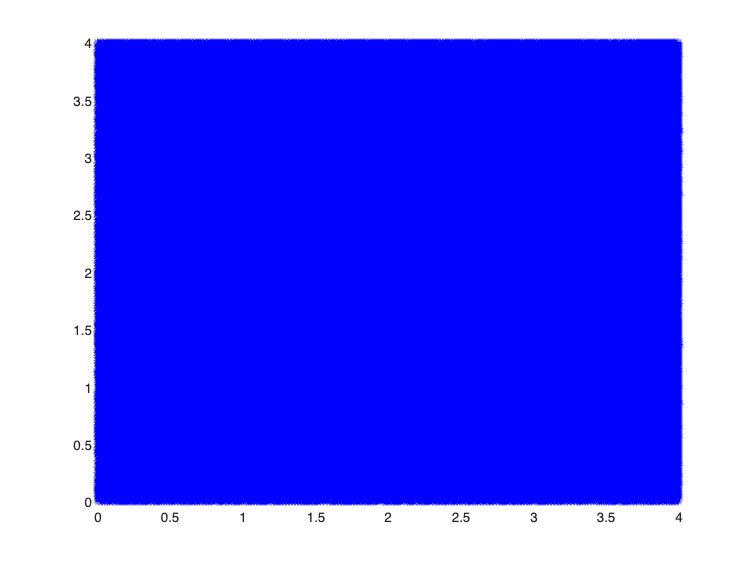

a = 0; b = 4;
x = a+ (b-a)*rand(M,1);
y = a+ (b-a)*rand(M,1);
fplot(g, [a,b],'r'), hold on
plot(x,y,'b*'),hold off,grid


k=0;
for kk=1:M
    if y(kk)<=g(x(kk))
        k = k+1;
    end
end
k

k = 500014

area = ((b-a)^2*k/M)

area = 8.0002

%cercle de radi 1 i centre(0,0)
% sector de cercle
m = 100000;
% x^2+y^2 <= 1
f =  @(x,y)x.^2+y.^2;
x = rand(m,1);
y = rand(m,1);
k = 0;
for i = 1:m
    if f(x(i),y(i)) <= 1
        k = k+1;
    end
end
I = k/m

I = 0.7870

dc = abs(pi-4*I)

dc = 0.0064


% tot el cercle
m = 100000;
% x^2+^2 <= 1
f =  @(x,y)x.^2+y.^2;
a = -1; b = 1;
x = a+(b-a)*rand(m,1);
y = a+(b-a)*rand(m,1);
k = 0;
for i = 1:m
    if f(x(i),y(i)) <= 1
        k = k+1;
    end
end
I = (b-a)*2*k/m

I = 3.1433

dc = abs(pi-I)

dc = 0.0017

## 3 AUTOAVALUACIÓ ....

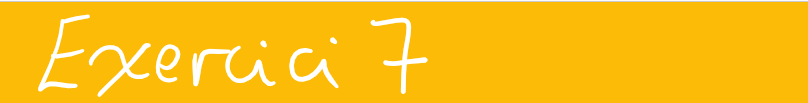

Calculeu la integral $\displaystyle I=\int_{-1}^{1} e^{-x^2}\,dx\,$

- a) Fent ús del mètode dels trapezis per $$h=\displaystyle\frac{1}{2^k},\ \ 0\leq k\leq 5.$

f = @(x) exp(-x.^2);
ve = integral(f,-1,1)

ve =           1.49364826562485

% Métode de Trapezis
k = 0:5; 
a = -1; 
b = 1;
my_trap(f,a,b,k);

    k       h             f(_)                 error            xifres
    _    _______    ________________    ____________________    ______
    0          1    1.36787944117144       0.125768824453412      0   
    1        0.5    1.46274050365713       0.030907761967728      1   
    2       0.25    1.48596819560076     0.00768007002409155      1   
    3      0.125    1.49173122969139     0.00191703593346326      2   
    4     0.0625    1.49316919357644    0.000479072048411355      3   
    5    0.03125    1.49352850930459    0.000119756320265507      3   


- b) Fent ús del mètode de Simpon per $$h=\displaystyle\frac{1}{2^k},\ \ 0\leq k\leq 5.$

% Mètode de Simpson
k = 0:5; 
a = -1; 
b = 1;
my_simp(f,a,b,k);

    k       h             f(_)                 error            xifres
    _    _______    ________________    ____________________    ______
    0          1    1.57858629411429       0.084938028489441      0   
    1        0.5    1.49436085781902    0.000712592194166639      2   
    2       0.25    1.49371075958197    6.24939571203242e-05      3   
    3      0.125    1.49365224105493    3.97543007935042e-06      5   
    4     0.0625    1.49364851487146    2.49246606687237e-07      6   
    5    0.03125    1.49364828121397    1.55891162201272e-08      7   


- c) Apliqueu el mètode de Romberg, fent ús dels resultats de l'apartat a) 

format longG
a = -1; b = 1; n = 5;
f = @(x)exp(-x.^2)

f = function_handle with value:
    @(x)exp(-x.^2)

IRom = romberg(f, a , b, 5 )

IRom =          0.735758882342885                         0                         0                         0                         0
          1.36787944117144          1.57858629411429                         0                         0                         0
          1.46274050365713          1.49436085781902          1.48874582873267                         0                         0
          1.48596819560076          1.49371075958197           1.4936674196995          1.49374554019104                         0
          1.49173122969139          1.49365224105493           1.4936483398198          1.49364803696456          1.49364765459897


it = simp(f,a,b,5)

it =           1.49367410982069


format longG
vc = integral(@(x)f(x),0,0.8,'RelTol',1e-8,'AbsTol',0.5e-16);

r = romberg(f,0,0.8,4)

r =          0.610916969617219                         0                         0                         0
         0.646316000395094         0.658115677321053                         0                         0
         0.654851153242218         0.657696204191259          0.65766823931594                         0
         0.656966396248731         0.657671477250902         0.657669828788211          0.65766985401793


abs(round(r - tril(vc*ones(size(r))),3,'significant'))

ans =                     0.0468                         0                         0                         0
                    0.0114                  0.000446                         0                         0
                   0.00282                  2.63e-05                  1.62e-06                         0
                  0.000703                  1.62e-06                  2.75e-08                  2.31e-09


- d) Fent ús de mètodes de simulació de MonteCarlo, per mostres de tamany $$M={10^k},\ \ 1\leq k\leq 7.$$

% Mètode de Montecarlo
format longG
a = -1; b = 1; k = 1:6;
montecarloFuncio(f,a,b,k);

    k       M             f(_)                 error            xifres
    _    _______    ________________    ____________________    ______
    1         10     1.4212582448647      0.0723900207601544      0   
    2        100    1.43260555852043      0.0610427071044244      0   
    3       1000    1.51313960935198      0.0194913437271234      1   
    4      10000    1.49314841368723    0.000499851937625584      3   
    5     100000    1.49345721921465     0.00019104641020018      3   
    6    1000000    1.49363127618741    1.69894374444368e-05      4   


- e)  Doneu els decimals exactes i les xifres significatives del les vostres aproximacions, sabent que  $$\displaystyle\int_0^t e^{-x^2}\,dx\, = \sqrt{\pi}\,erf\left(t\right).$$ Consulteu l'ajuda de Matlab per la funció `erf.`

`Document preparat per M. Àngela Grau Gotés - 3 de maig de 2022`

% Codis de les 

function r = midp(f,a,b,n)
h = (b - a) / n;
x = a + h * 0.5;
r = 0;
for i=1:n
    r = r + f(x);
    x = x + h;
end;
r = r * h;
end
%%-----------------------
function r = trap(f,a,b,n)
h = (b - a) / n;
r = f(a) * 0.5;
x = a + h;
for i = 1 : n-1
    r = r + f(x);
    x = x + h;
end;
r = r + f(b) * 0.5;
r = r * h;
end
%%-----------------------
function r = simp(f,a,b,n)
h = (b - a) / (n * 2);
r = f(a);
x = a + h;
for i = 1 : n-1
    r = r + 4 * f(x);
    x = x + h;
    r = r + 2 * f(x);
    x = x + h;
end;
r = r + 4 * f(x);
r = r + f(b);
r = r * h/3;
end
%----------------------------
function r = romberg(f,a,b,n)
h = (b - a) ./ (2.^(0:n-1));
r(1,1) = (b - a) * (f(a) + f(b)) / 2;
for j = 2:n
    subtotal = 0;
    for i = 1:2^(j-2)
        subtotal = subtotal + f(a + (2 * i - 1) * h(j));
    end
    r(j,1) = r(j-1,1) / 2 + h(j) * subtotal;
    for k = 2:j
        r(j,k) = (4^(k-1) * r(j,k-1) - r(j-1,k-1)) / (4^(k-1) - 1);
    end
end;
end
%%---------------
function y = myF(x)
    y = sin(x)./x;
    if isnan(y)
        y = 1;
    end
end 

function valor = my_trap(f,a,b,k)
    n = length(k); TT = [];
    ve = integral(f,a,b);
    for i = 1:n
        h = 1/(2^k(i));
        x = a:h:b; y = f(x);
        w = [1 2*ones(1,length(y)-2) 1];
        valor = sum(y.*w*(h/2));
        TT = [TT; k(i), h, valor, abs(valor-ve), fix(-log10(2*abs(valor-ve)))];
    end
    taula = array2table(TT,'VariableNames',{'k','h','f(_)','error','xifres'}); 
    disp(taula)
end

function valor = my_simp(f,a,b,k)
    n = length(k); TS = [];
    ve = integral(f,a,b);
    for i = 1:n
        h = 1/(2^k(i));
        x = a:h:b; y = f(x);
        w = 4*ones(1,length(y)-2);
        w(2:2:end) = 2;
        w = [1 w 1];
        valor = sum(y.*w*(h/3));
        TS = [TS; k(i), h, valor, abs(valor-ve), fix(-log10(2*abs(valor-ve)))];
    end
    taula = array2table(TS,'VariableNames',{'k','h','f(_)','error','xifres'});
    disp(taula)
end

function montecarloFuncio(f,a,b,k)
    n = length(k); TM = [];
    ve = integral(f,a,b);
    for i = 1:n
        m = 10^k(i);
        x = a+(b-a)*rand(m,1);
        valor = (b-a)*sum(f(x))/m;
        TM = [TM; k(i), m, valor, abs(valor-ve), fix(-log10(2*abs(valor-ve)))];
    end
    taula = array2table(TM,'VariableNames',{'k','M','f(_)','error', 'xifres'});
    disp(taula)
end